# Part 1: Separation vs. Isolation, physical interactions

In progress! Updated 12/2/2022 (line 236)

## 0. Indices 

rat_adc_ind = intersect(ya_ind, rat_ind);
[u_pairs_rc, ia_rat, ic_rat] = unique(rdb.paircode(rat_adc_ind));
parfind_rc = cell(length(u_pairs_rc),1);
 for i = 1:length(u_pairs_rc)
     parfind_rc{i} = intersect(find(rdb.paircode == u_pairs_rc(i)), ya_ind);
 end
 
 rat_adt_ind = intersect(ya_ind, rat_ind);
[u_pairs_rt, ia_rat, ic_rat] = unique(rdb.paircode(rat_adt_ind));
parfind_rt = cell(length(u_pairs_rt),1);
 for i = 1:length(u_pairs_rt)
     parfind_rt{i} = intersect(find(rdb.paircode == u_pairs_rt(i)), ya_ind);
 end

 u_pairs = u_pairs_rc;

betypes = [-1 1 2 3 5 4];
 behaves2use = 1:5;
  behaviortypes = {'wrestling' 'mounting' 'grooming' 'rear-sniffing' 'face-to-face' 'body-sniffing' 'huddling'};
 phystypes = betypes; %might have used wrong variable name so this is just a catch 
 

## I. Physical interactions, total time

### A. Physical interactions, combined

u_pairs = u_pairs_rc;
parfind = parfind_rc;

    septime_mat = nan(length(u_pairs),length(cofind),length(betypes));
    septime_new = nan(length(u_pairs), length(cofind), length(betypes_n));
        for i = 1:size(u_pairs,1)
            for j = 1:length(cofind)
                curind = intersect(parfind{i}, cofind{j});
                if ~isempty(curind)
                    septime_mat(i,j,1:length(betypes)) = sumbehav(curind,:);
                    septime_new(i,j,1:length(betypes_n)) = sumbehav_new(curind,:);
                end
            end
        end

        septime_new = cat(3, septime_new, septime_mat(:,:,2:end));
       

Figure of total physical interaction data

   
        
        stm_all = nansum(septime_mat(:,:,behaves2use),3);
    stm_all(stm_all == 0) = nan;
 
% not normalized:
f = figure

f =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [573 544 560 420]
       Units: 'pixels'

  Show all properties


f2A = get(figure, 'Children')

f2A =   0×0 empty GraphicsPlaceholder array.


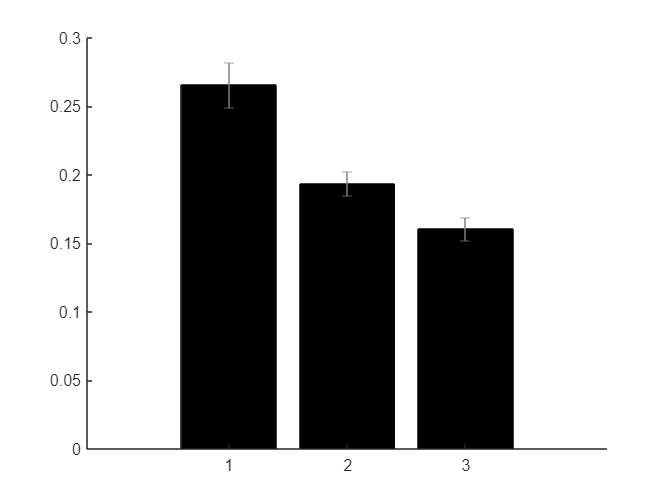

%    f2A = subplot(1,2,);
    bar(1:3, nanmean(stm_all), 'FaceColor', 'k');
    hold on;
    eb = errorbar(1:3, nanmean(stm_all), nanstd(stm_all)/sqrt(size(septime_mat,1)-1), 'LineStyle', 'none', 'Color', [.5 .5 .5]);
    set(f2A, 'XTickLabel', xticklabels);
    set(get(f2A, 'XLabel'), 'String', 'condition');
    set(get(f2A, 'YLabel'), 'String', 'proportion of time');
    set(get(f2A, 'Title'), 'String', 'All Physical Interactions');
    box off

 
    maxy = get(f2A, 'YLim');


tbl = simple_mixed_anova(stm_all.^(1/3), [], {'exp_cond'})

tbl = 4×8 table
                             SumSq      DF     MeanSq        F         pValue       pValueGG      pValueHF      pValueLB 
                            ________    __    _________    ______    __________    __________    __________    __________

    (Intercept)               12.182     1       12.182    1784.6    1.5922e-13    1.5922e-13    1.5922e-13    1.5922e-13
    Error                   0.075088    11    0.0068262                                                                  
    (Intercept):exp_cond    0.053961     2      0.02698    10.776    0.00054649     0.0016535    0.00094863     0.0072991
    Error(exp_cond)         0.055

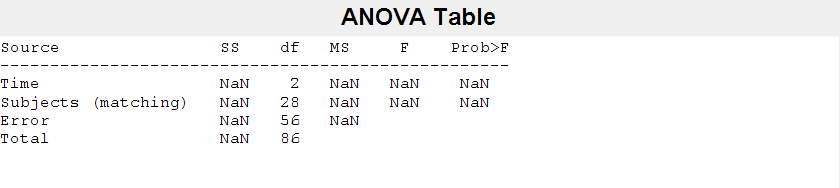

 [p2, table] = anova_rm(stm_all);

 
 [a b] = ttest(stm_all(:,2)-stm_all(:,3))

a = 1

b = 0.0390

[a b] = ttest(stm_all(:,1)-stm_all(:,3))

a = 1

b = 0.0012

 [a b] = ttest(stm_all(:,1)-stm_all(:,2))

a = 1

b = 0.0067

### B. Physical interaction types

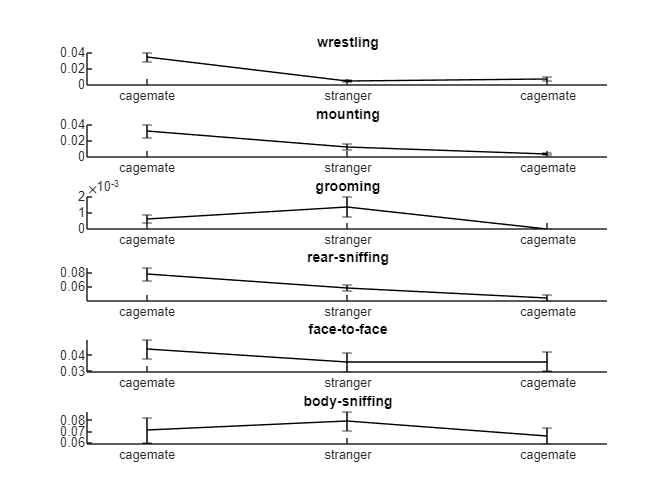


 behaves2use = 1:6;

figure
 for i = 1:length(behaves2use)
%     f2B = subplot(4,3,i*3);
    f2B = subplot(length(behaves2use),1,i);
     %bar(1:3, nanmean(septime_mat(:,:,i)));
     hold on
     e_sub = errorbar(1:3, nanmean(septime_new(:,:,i)), nanstd(septime_new(:,:,i))/sqrt(size(septime_new,1)-1), 'k'); %'LineStyle', 'none');
%    ax = gca;
%    ax.Clipping = 'off';
    set(f2B, 'XTick', [1:3]);
     set(f2B, 'XTickLabel', xticklabels);
  %  set(get(f1B, 'XLabel'), 'String', 'condition');
 %   set(get(f1B, 'YLabel'), 'String', 'proportion of time');
    set(get(f2B, 'Title'), 'String', behaviortypes{i});
    set(get(e_sub, 'Parent'), 'XLim', [.7 3.3]);
     box off
 end

 behaves2use = [1:5];
 f2B = cell(6,1);
 t = cell(6,1);
%figure
 for j = 1:length(behaves2use)

%         fprintf('species: %d, behavior: %d', i, j);
% % not normalized:
%         f2B{j} = subplot(length(behaves2use),1,j);
%         bar(1:3, nanmean(septime_mat(:,:,j)), 'FaceColor', 'k');
%         hold on;
%         eb = errorbar(1:3, nanmean(septime_mat(:,:,j)), nanstd(septime_mat(:,:,j))/sqrt(size(septime_mat,1)-1), 'LineStyle', 'none', 'Color', [.5 .5 .5]);
%         set(f2B{j}, 'XTickLabel', xticklabels);
%         if j == length(behaves2use)
%             set(get(f2B{j}, 'XLabel'), 'String', 'condition');
%         end
%         if j == 3
%             set(get(f2B{j}, 'YLabel'), 'String', 'proportion of time');
% %        set(get(f2B{i,j}, 'Title'), 'String', 'All Physical Interactions');
%         end
%         box off

  
        t{j} = simple_mixed_anova(septime_new(:,:,j).^(1/3), [], {'exp_cond'});
        [a_is(j) b_is(j)] = ttest(septime_new(:,1,j).^(1/3) - septime_new(:,2,j).^(1/3)) ;
       [a_ic(j) b_ic(j)] = ttest(septime_new(:,1,j).^(1/3) - septime_new(:,3,j).^(1/3)) ;
        [a_sc(j) b_sc(j)] = ttest(septime_new(:,2,j).^(1/3) - septime_new(:,3,j).^(1/3)) ;



%         stm = [septime_mat(:,:,j) ; septime_mat(:,:,j)];
%         tmp = simple_mixed_anova(stm.^(1/3), [ones(13,1); zeros(10,1)], {'exp_cond'}, {'species'})
%         tblB{j} = tmp;
 end
 for j = 1:length(behaves2use)
     fprintf('behavior: %s', behaviortypes{j});
     t{j}
 end

behavior: wrestling

ans = 4×8 table
                             SumSq     DF     MeanSq       F         pValue       pValueGG      pValueHF      pValueLB 
                            _______    __    ________    ______    __________    __________    __________    __________

    (Intercept)             0.87368     1     0.87368    38.128    6.9592e-05    6.9592e-05    6.9592e-05    6.9592e-05
    Error                   0.25206    11    0.022915                                                                  
    (Intercept):exp_cond    0.26539     2      0.1327    12.019    0.00029668     0.0005117    0.00029668     0.0052687
    Error(exp_cond)         0.24289    22  

behavior: mounting

ans = 4×8 table
                             SumSq      DF     MeanSq        F        pValue     pValueGG    pValueHF    pValueLB
                            ________    __    _________    ______    ________    ________    ________    ________

    (Intercept)              0.75695     1      0.75695    13.405    0.003746    0.003746    0.003746    0.003746
    Error                    0.62113    11     0.056466                                                          
    (Intercept):exp_cond    0.052799     2     0.026399     2.894      0.0766     0.10725     0.10416     0.11697
    Error(exp_cond)          0.20069    22    0.0091222                  

behavior: grooming

ans = 4×8 table
                              SumSq      DF     MeanSq        F        pValue     pValueGG    pValueHF    pValueLB
                            _________    __    _________    ______    ________    ________    ________    ________

    (Intercept)              0.014083     1     0.014083    5.3425    0.041199    0.041199    0.041199    0.041199
    Error                    0.028996    11     0.002636                                                          
    (Intercept):exp_cond    0.0073589     2    0.0036795    1.0273     0.37453     0.35416     0.35983     0.33258
    Error(exp_cond)            0.0788    22    0.0035818            

behavior: rear-sniffing

ans = 4×8 table
                             SumSq      DF     MeanSq        F         pValue       pValueGG      pValueHF      pValueLB 
                            ________    __    _________    ______    __________    __________    __________    __________

    (Intercept)               5.0296     1       5.0296    606.93    5.6515e-11    5.6515e-11    5.6515e-11    5.6515e-11
    Error                   0.091155    11    0.0082868                                                                  
    (Intercept):exp_cond    0.020373     2     0.010187    2.9993      0.070496       0.08345      0.074439       0.11121
    Error(exp_cond)          0.07

behavior: face-to-face

ans = 4×8 table
                              SumSq      DF     MeanSq        F         pValue       pValueGG      pValueHF      pValueLB 
                            _________    __    _________    ______    __________    __________    __________    __________

    (Intercept)                3.3159     1       3.3159    111.73    4.2368e-07    4.2368e-07    4.2368e-07    4.2368e-07
    Error                     0.32647    11     0.029679                                                                  
    (Intercept):exp_cond    0.0060826     2    0.0030413    2.5581       0.10027       0.10892       0.10027       0.13804
    Error(exp_cond)         

 b_is

b_is =     0.0033    0.1361    0.8200    0.3974    0.1015


 b_ic

b_ic =     0.0007    0.1010    0.1659    0.0344    0.0229


 b_sc

b_sc =     0.9574    0.1650    0.1675    0.0683    0.8253


### C. Distribution over time

% A.Cumulative activity over time
cumsumbehav = Rdb_CumSum2(rdb, betypes(1:5), 1);

csum = sum(cumsumbehav, 3);

 cumsum_f_a_d1 = nan(length(u_pairs), 601, length(cofind));
h_cs_f_a = nan(length(u_pairs), length(cofind));
 
 for k = 1:length(cofind)
    for i = 1:size(u_pairs,1)
        
        curind = intersect(find(rdb.paircode == u_pairs(i)), cofind{k});
        if ~isempty(curind)
            cumsum_f_a_d1(i,:,k) = csum(curind,:);
        %    h_cs_f_a(i,k) = csum_ht(curind);
        end
        
    end
 end

Display cumsums

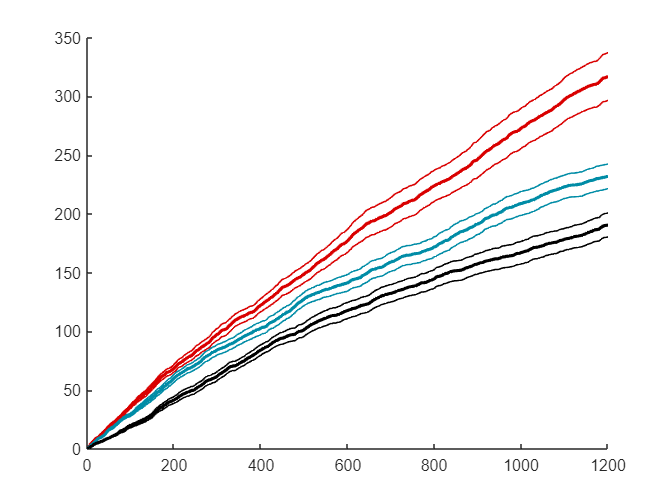

 figure
% errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 1)), nanstd(cumsum_f_a_d1(:, :, 1))/sqrt(length(u_paircodes)-1), 'k:');
% hold on
% errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 2)), nanstd(cumsum_f_a_d1(:, :, 2))/sqrt(length(u_paircodes)-1), 'k--');
% errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 3)), nanstd(cumsum_f_a_d1(:, :, 3))/sqrt(length(u_paircodes)-1), 'k-');
% 

errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 1)), nanstd(cumsum_f_a_d1(:, :, 1))/sqrt(length(u_pairs)-1), 'Color', [.85 0 0]);
hold on
errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 2)), nanstd(cumsum_f_a_d1(:, :, 2))/sqrt(length(u_pairs)-1), 'Color', [0 .55 .65]);
errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 3)), nanstd(cumsum_f_a_d1(:, :, 3))/sqrt(length(u_pairs)-1), 'Color', [0 0 0]);

box off

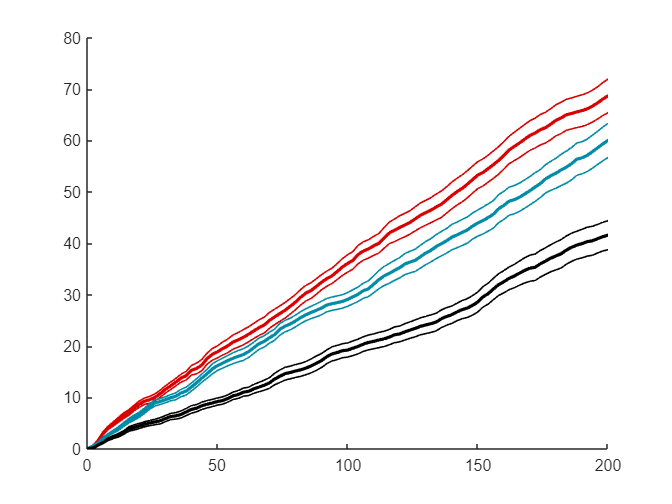

figure
e2 = errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 1)), nanstd(cumsum_f_a_d1(:, :, 1))/sqrt(length(u_pairs)-1), 'Color', [.85 0 0]);
hold on
errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 2)), nanstd(cumsum_f_a_d1(:, :, 2))/sqrt(length(u_pairs)-1), 'Color', [0 .55 .65]);
errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 3)), nanstd(cumsum_f_a_d1(:, :, 3))/sqrt(length(u_pairs)-1), 'Color', [0 0 0]);
set(get(e2{1}, 'Parent'), 'XLim', [0 200]);
set(get(e2{1}, 'Parent'), 'YLim', [0 80]);


box off

for i = 1:length(cumsum_f_a_d1)

    [~, is_cumsum(i)] = ttest(cumsum_f_a_d1(:,i,1) - cumsum_f_a_d1(:,i,2));
    [~, ic_cumsum(i)] = ttest(cumsum_f_a_d1(:,i,1) - cumsum_f_a_d1(:,i,3));
    [~, sc_cumsum(i)] = ttest(cumsum_f_a_d1(:,i,2) - cumsum_f_a_d1(:,i,3));
end

sc_cumsum

sc_cumsum =        NaN    0.0645    0.3252    0.1003    0.0666    0.0662    0.1028    0.0789    0.1587    0.1704    0.1435    0.0826    0.0531    0.0453    0.0535    0.0560    0.0537    0.0612    0.0522    0.0687    0.0565    0.0267    0.0185    0.0120    0.0086    0.0045    0.0031    0.0027    0.0044    0.0060    0.0099    0.0083    0.0067    0.0054    0.0050    0.0041    0.0064    0.0054    0.0057    0.0059    0.0047    0.0035    0.0034    0.0044    0.0071    0.0078    0.0080    0.0084    0.0096    0.0091


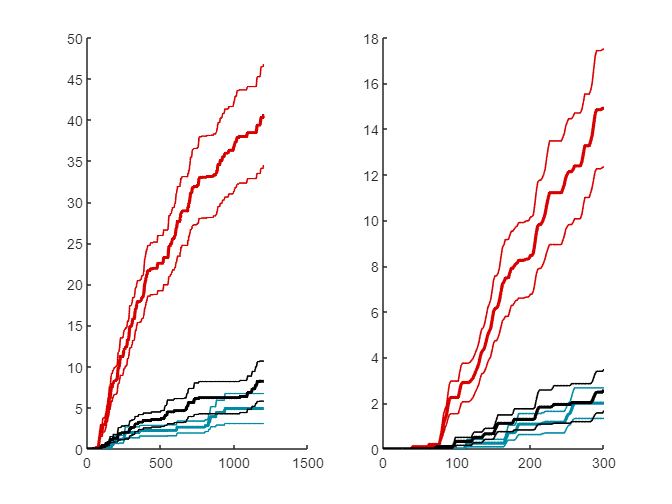

sc_cumsum_b = 5×1 cell array
    {[NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.7939 0.5500 0.5500 0.5500 0.5500 0.9541 0.9570 0.9570 0.9570 0.9570 0.9570 0.9570 0.7954 0.6625 0.6625 0.6625 0.6625 0.6625 0.6625 0.6276 0.4237 0.3348 0.3048 0.3048 0.3048 0.3048 0.3048 0.4129 0.5958 0.7840 0.7842 0.7842 0.7690 0.6691 0.6974 0.8394 0.9697 0.9697 0.9697 0.9697 0.9697 0.9697 0.9697 0.9697 0.9697 0.9697 0.9697 0.9417 0.7967 0.7164 0.6813 0.6813 0.7017 0.7017 0.7247 0.7247 0.7247 0.7247 0.7247 0.7108 0.6853 0.6853 0.6853 0.6853 0.6853 0.6853 0.6853 0.6853 0.7175 0.7797 0.8164 0.8368 0.8775 0.9839 0.9397 0.9397 0.9397 0.9397 0.9397 0.9397 0.9397 0.9397 0.9397 0.9397 0.9397 0.9397 0.9397 0.9397 0.9397 0.9397 0.9397 0.9397 0.9397 0.9397 0.9828 0.9828 0.9828 0.

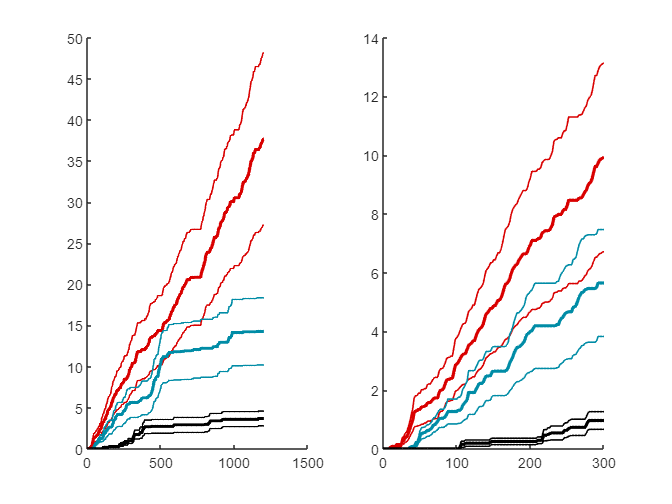

sc_cumsum_b = 5×1 cell array
    {[                                                      NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.7939 0.5500 0.5500 0.5500 0.5500 0.9541 0.9570 0.9570 0.9570 0.9570 0.9570 0.9570 0.7954 0.6625 0.6625 0.6625 0.6625 0.6625 0.6625 0.6276 0.4237 0.3348 0.3048 0.3048 0.3048 0.3048 0.3048 0.4129 0.5958 0.7840 0.7842 0.7842 0.7690 0.6691 0.6974 0.8394 0.9697 0.9697 0.9697 0.9697 0.9697 0.9697 0.9697 0.9697 0.9697 0.9697 0.9697 0.9417 0.7967 0.7164 0.6813 0.6813 0.7017 0.7017 0.7247 0.7247 0.7247 0.7247 0.7247 0.7108 0.6853 0.6853 0.6853 0.6853 0.6853 0.6853 0.6853 0.6853 0.7175 0.7797 0.8164 0.8368 0.8775 0.9839 0.9397 0.9397 0.9397 0.9397 0.9397 0.9397 0.9397 0.9397 0.9397 0.9397 0.9397 0.9397 0.9397 0.9397 0.9397 0.93

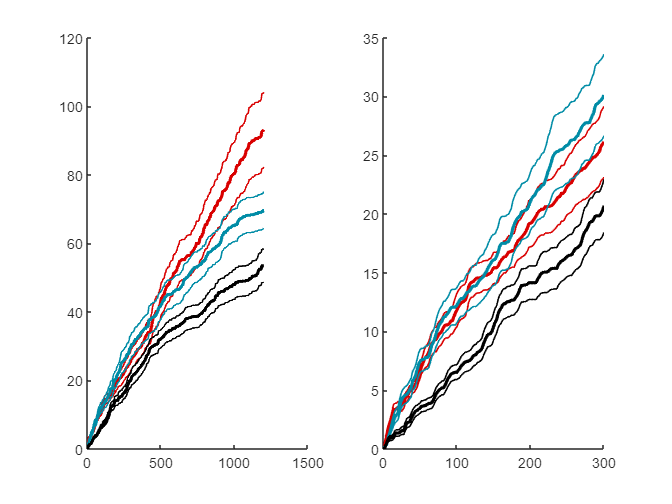

sc_cumsum_b = 5×1 cell array
    {[                                                                                                         NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.7939 0.5500 0.5500 0.5500 0.5500 0.9541 0.9570 0.9570 0.9570 0.9570 0.9570 0.9570 0.7954 0.6625 0.6625 0.6625 0.6625 0.6625 0.6625 0.6276 0.4237 0.3348 0.3048 0.3048 0.3048 0.3048 0.3048 0.4129 0.5958 0.7840 0.7842 0.7842 0.7690 0.6691 0.6974 0.8394 0.9697 0.9697 0.9697 0.9697 0.9697 0.9697 0.9697 0.9697 0.9697 0.9697 0.9697 0.9417 0.7967 0.7164 0.6813 0.6813 0.7017 0.7017 0.7247 0.7247 0.7247 0.7247 0.7247 0.7108 0.6853 0.6853 0.6853 0.6853 0.6853 0.6853 0.6853 0.6853 0.7175 0.7797 0.8164 0.8368 0.8775 0.9839 0.9397 0.9397 0.9397 0.9397 0.9397 0.9397 0.9397 0.9397 0.

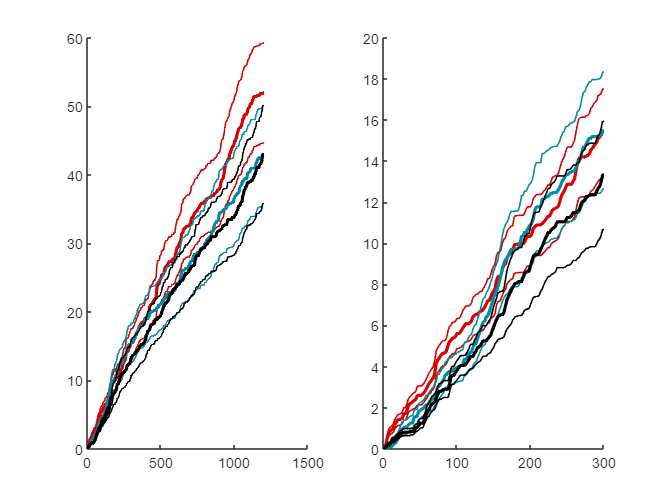

sc_cumsum_b = 5×1 cell array
    {[                                                                                                         NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.7939 0.5500 0.5500 0.5500 0.5500 0.9541 0.9570 0.9570 0.9570 0.9570 0.9570 0.9570 0.7954 0.6625 0.6625 0.6625 0.6625 0.6625 0.6625 0.6276 0.4237 0.3348 0.3048 0.3048 0.3048 0.3048 0.3048 0.4129 0.5958 0.7840 0.7842 0.7842 0.7690 0.6691 0.6974 0.8394 0.9697 0.9697 0.9697 0.9697 0.9697 0.9697 0.9697 0.9697 0.9697 0.9697 0.9697 0.9417 0.7967 0.7164 0.6813 0.6813 0.7017 0.7017 0.7247 0.7247 0.7247 0.7247 0.7247 0.7108 0.6853 0.6853 0.6853 0.6853 0.6853 0.6853 0.6853 0.6853 0.7175 0.7797 0.8164 0.8368 0.8775 0.9839 0.9397 0.9397 0.9397 0.9397 0.9397 0.9397 0.9397 0.9397 0.

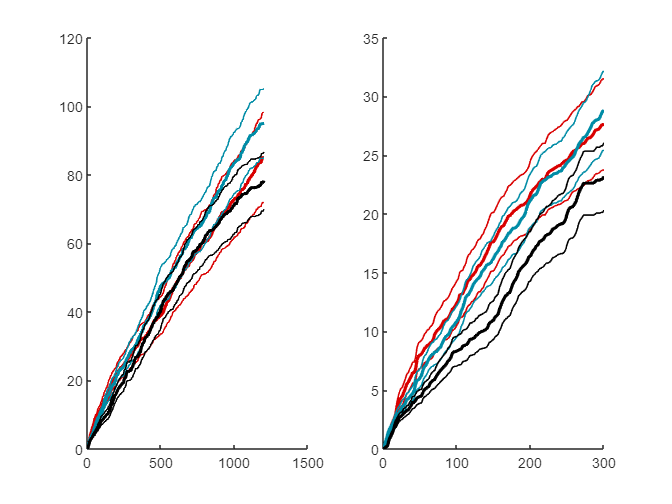

sc_cumsum_b = 5×1 cell array
    {[                                                                                                         NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.3388 0.7939 0.5500 0.5500 0.5500 0.5500 0.9541 0.9570 0.9570 0.9570 0.9570 0.9570 0.9570 0.7954 0.6625 0.6625 0.6625 0.6625 0.6625 0.6625 0.6276 0.4237 0.3348 0.3048 0.3048 0.3048 0.3048 0.3048 0.4129 0.5958 0.7840 0.7842 0.7842 0.7690 0.6691 0.6974 0.8394 0.9697 0.9697 0.9697 0.9697 0.9697 0.9697 0.9697 0.9697 0.9697 0.9697 0.9697 0.9417 0.7967 0.7164 0.6813 0.6813 0.7017 0.7017 0.7247 0.7247 0.7247 0.7247 0.7247 0.7108 0.6853 0.6853 0.6853 0.6853 0.6853 0.6853 0.6853 0.6853 0.7175 0.7797 0.8164 0.8368 0.8775 0.9839 0.9397 0.9397 0.9397 0.9397 0.9397 0.9397 0.9397 0.9397 0.

betypes_c = [-1.7 -1 2 3 5];

cumsumbehav = Rdb_CumSum2(rdb, betypes_c, 1);



cumsum_b = cell(length(betypes_c),1);
is_cumsum_b = cell(length(betypes_c),1);
ic_cumsum_b = cell(length(betypes_c),1);
sc_cumsum_b = cell(length(betypes_c),1);

for j = 1:length(betypes_c)
     cumsum_b{j} = nan(length(u_pairs), 601, length(cofind));
    h_cs_f_a = nan(length(u_pairs), length(cofind));
 
     for k = 1:length(cofind)
        for i = 1:size(u_pairs,1)
        
            curind = intersect(find(rdb.paircode == u_pairs(i)), cofind{k});
            if ~isempty(curind)
                cumsum_b{j}(i,:,k) = cumsumbehav(curind,:,j);
           end
        
        end
     end
      figure
        % errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 1)), nanstd(cumsum_f_a_d1(:, :, 1))/sqrt(length(u_paircodes)-1), 'k:');
        % hold on
        % errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 2)), nanstd(cumsum_f_a_d1(:, :, 2))/sqrt(length(u_paircodes)-1), 'k--');
        % errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 3)), nanstd(cumsum_f_a_d1(:, :, 3))/sqrt(length(u_paircodes)-1), 'k-');
        % 

        subplot(1,2,1)
        errorbar_alt(0:2:1200, nanmean(cumsum_b{j}(:, :, 1)), nanstd(cumsum_b{j}(:, :, 1))/sqrt(length(u_pairs)-1), 'Color', [.85 0 0]);
        hold on
        errorbar_alt(0:2:1200, nanmean(cumsum_b{j}(:, :, 2)), nanstd(cumsum_b{j}(:, :, 2))/sqrt(length(u_pairs)-1), 'Color', [0 .55 .65]);
        errorbar_alt(0:2:1200, nanmean(cumsum_b{j}(:, :, 3)), nanstd(cumsum_b{j}(:, :, 3))/sqrt(length(u_pairs)-1), 'Color', [0 0 0]);

        box off

        subplot(1,2,2)
        errorbar_alt(0:2:300, nanmean(cumsum_b{j}(:, 1:151, 1)), nanstd(cumsum_b{j}(:, 1:151, 1))/sqrt(length(u_pairs)-1), 'Color', [.85 0 0]);
        hold on
        errorbar_alt(0:2:300, nanmean(cumsum_b{j}(:, 1:151, 2)), nanstd(cumsum_b{j}(:, 1:151, 2))/sqrt(length(u_pairs)-1), 'Color', [0 .55 .65]);
        errorbar_alt(0:2:300, nanmean(cumsum_b{j}(:, 1:151, 3)), nanstd(cumsum_b{j}(:, 1:151, 3))/sqrt(length(u_pairs)-1), 'Color', [0 0 0]);

        box off

        

        for i = 1:length(cumsum_f_a_d1)

            [~, is_cumsum_b{j}(i)] = ttest(cumsum_b{j}(:,i,1) - cumsum_b{j}(:,i,2));
            [~, ic_cumsum_b{j}(i)] = ttest(cumsum_b{j}(:,i,1) - cumsum_b{j}(:,i,3));
            [~, sc_cumsum_b{j}(i)] = ttest(cumsum_b{j}(:,i,2) - cumsum_b{j}(:,i,3));
        end
            sc_cumsum_b
       
end

Ratio of mounting to playing

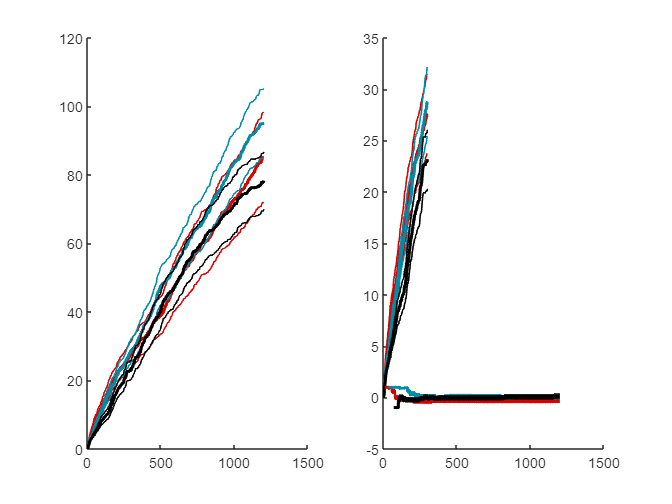

cumsum_m2p = (cumsum_b{2}-cumsum_b{1})./(cumsum_b{2} + cumsum_b{1});    


errorbar_alt(0:2:1200, nanmean(cumsum_m2p(:, :, 1)), nanstd(cumsum_m2p(:, :, 1))/sqrt(length(u_pairs)-1), 'Color', [.85 0 0]);
        hold on
        errorbar_alt(0:2:1200, nanmean(cumsum_m2p(:, :, 2)), nanstd(cumsum_m2p(:, :, 2))/sqrt(length(u_pairs)-1), 'Color', [0 .55 .65]);
        errorbar_alt(0:2:1200, nanmean(cumsum_m2p(:, :, 3)), nanstd(cumsum_m2p(:, :, 3))/sqrt(length(u_pairs)-1), 'Color', [0 0 0]);

        box off

Repeat in adults

        
u_pairs = u_pairs_rt;
parfind = parfind_rt;

    septime_mat = nan(length(u_pairs),length(cofind),length(betypes));
    septime_new = nan(length(u_pairs), length(cofind), length(betypes_n));
        for i = 1:size(u_pairs,1)
            for j = 1:length(cofind)
                curind = intersect(parfind{i}, cofind{j});
                if ~isempty(curind)
                    septime_mat(i,j,1:length(betypes)) = sumbehav(curind,:);
                    septime_new(i,j,1:length(betypes_n)) = sumbehav_new(curind,:);
                end
            end
        end

        septime_new = cat(3, septime_new, septime_mat(:,:,2:end));

        

        stm_all = nansum(septime_mat(:,:,behaves2use),3);
    stm_all(stm_all == 0) = nan;
 
% not normalized:
f = figure

f =   Figure (12) with properties:

      Number: 12
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [573 544 560 420]
       Units: 'pixels'

  Show all properties


f2A = get(figure, 'Children')

f2A =   0×0 empty GraphicsPlaceholder array.


%    f2A = subplot(1,2,);
    bar(1:3, nanmean(stm_all), 'FaceColor', 'k');
    hold on;
    eb = errorbar(1:3, nanmean(stm_all), nanstd(stm_all)/sqrt(size(septime_mat,1)-1), 'LineStyle', 'none', 'Color', [.5 .5 .5]);
    set(f2A, 'XTickLabel', xticklabels);
    set(get(f2A, 'XLabel'), 'String', 'condition');
    set(get(f2A, 'YLabel'), 'String', 'proportion of time');
    set(get(f2A, 'Title'), 'String', 'All Physical Interactions');
    box off

 
    maxy = get(f2A, 'YLim');


tbl = simple_mixed_anova(stm_all.^(1/3), [], {'exp_cond'})

tbl = 4×8 table
                             SumSq      DF     MeanSq        F         pValue       pValueGG      pValueHF      pValueLB 
                            ________    __    _________    ______    __________    __________    __________    __________

    (Intercept)               12.182     1       12.182    1784.6    1.5922e-13    1.5922e-13    1.5922e-13    1.5922e-13
    Error                   0.075088    11    0.0068262                                                                  
    (Intercept):exp_cond    0.053961     2      0.02698    10.776    0.00054649     0.0016535    0.00094863     0.0072991
    Error(exp_cond)         0.055

 [p2, table] = anova_rm(stm_all);

 
 [a b] = ttest(stm_all(:,2)-stm_all(:,3))

a = 1

b = 0.0390

[a b] = ttest(stm_all(:,1)-stm_all(:,3))

a = 1

b = 0.0012

 [a b] = ttest(stm_all(:,1)-stm_all(:,2))

a = 1

b = 0.0067

 behaves2use = 1:6;

figure
 for i = 1:length(behaves2use)
%     f2B = subplot(4,3,i*3);
    f2B = subplot(length(behaves2use),1,i);
     %bar(1:3, nanmean(septime_mat(:,:,i)));
     hold on
     e_sub = errorbar(1:3, nanmean(septime_new(:,:,i)), nanstd(septime_new(:,:,i))/sqrt(size(septime_new,1)-1), 'k'); %'LineStyle', 'none');
%    ax = gca;
%    ax.Clipping = 'off';
    set(f2B, 'XTick', [1:3]);
     set(f2B, 'XTickLabel', xticklabels);
  %  set(get(f1B, 'XLabel'), 'String', 'condition');
 %   set(get(f1B, 'YLabel'), 'String', 'proportion of time');
    set(get(f2B, 'Title'), 'String', behaviortypes{i});
    set(get(e_sub, 'Parent'), 'XLim', [.7 3.3]);
     box off
 end

Latency data: Compute the matrix for this experiment

latmat_f = nan(length(u_pairs), length(phystypes), length(cofind));
latmat5_f = nan(length(u_pairs), length(phystypes), length(cofind));
 for i = 1:length(u_pairs)
     for k = 1:length(cofind)
         curind = intersect(find(rdb.degunumbers(:,1) == u_pairs(i,1) & rdb.degunumbers(:,2) == u_pairs(i,2)), cofind{k});
         latmat_f(i,:, k) = be_lat(curind,:);    
         latmat5_f(i,:,k) = be_lat5(curind,:);
     end
 end

Unrecognized field name "degunumbers".

Display latencies, collective

 f = figure
lm = min(latmat_f, [], 2);
bar(nanmean(squeeze(lm)), 'k')
hold on
errorbar(1:3, nanmean(squeeze(lm)), nanstd(squeeze(lm))/sqrt(8), 'Color', [.5 .5 .5], 'LineStyle', 'none')
box off
set(get(f, 'Children'), 'XTick', [1:3])
set(get(f, 'Children'), 'XTickLabel', xticklabels);

slm = squeeze(lm);
p = anova_rm(squeeze(slm));

Display the latencies across types

titlecell = {'agonistic', 'body sniffing', 'rear sniffing', 'face-to-face'};

 figure
 
 for i = 1:length(betypes)
    d = subplot(length(betypes),1,i);
    
    errorbar(1:length(condvec), nanmean(squeeze(latmat5_f(:, i,:))), nanstd(squeeze(latmat5_f(:,i,:)))/sqrt(8), 'k');
%    hold  on
   set(d, 'XLim', [.75 3.25]);
   set(d, 'XTick', [1:3])
   if i < 4
       set(d, 'XTickLabel', {'' '' '' });
   else
       set(d, 'XTickLabel', xticklabels);
   end
   title(titlecell{i});
    box off
 end

Stats on latencies

for i = 1:4
    [a(i) b(i)] = ttest(squeeze(latmat5_f(:,i,1)- latmat5_f(:,i,2)));
  %   [psub(i,:) j] = anova_rm(squeeze(latmat5_f(:,i,1:2)));
%     sheetnum = ['Sheet' num2str(i)];
%     xlswrite('SeparationEffectOnPhysical_Sheets_1Agonistic_2groom_3rearsniff_4faceface.xls', septime_mat(:,:,i), sheetnum);       
end
b

### D. Temporal relationships between interactions


%  exp_ind = find(strcmp(rdb.experiment, 'cof'));
%  
%  cof_iso_ind = intersect(exp_ind, find(rdb.condition(:,4) == 0));
%  cof_sep_ind = intersect(exp_ind, find(rdb.condition(:,4) == 1));
%  cof_min_ind = intersect(exp_ind, find(rdb.condition(:,2) == 1/60));
%  
%  cofind = cell(3,1);
%  cofind{1} = cof_iso_ind;
%  cofind{2} = cof_sep_ind;
%  cofind{3} = cof_min_ind;


colorcodes = [.85 0 0; 0 .55 .65];

figure
%i = 1;
for i = 1:2
    for j = 1:16
        subplot(4,4,j);
        hold on
        curind = cofind{i};

        errorbar_alt(xaxis, nanmean(squeeze(be_xcorr(j,:,curind))'), nanstd(squeeze(be_xcorr(j,:,curind))')/sqrt(length(curind)-1), 'Color', colorcodes(i,:))  ;  
%        hold on
%        errorbar_alt(xaxis, nanmean(squeeze(SH_xcorr(j,:,curind))'), nanstd(squeeze(SH_xcorr(j,:,curind))')/sqrt(length(curind)-1), 'Color', colorcodes(2,:))  ; 
        box off
    end    
    
end


% stats 
mxc = nan(size(be_xcorr,1), 2, size(be_xcorr,3));

mxc(:,1,:) = nanmean(be_xcorr(:,1:19,:),2);
mxc(:,2,:) = nanmean(be_xcorr(:,23:42,:),2);

sxc(:,1,:) = nanmean(SH_xcorr(:,1:19,:),2);
sxc(:,2,:) = nanmean(SH_xcorr(:,23:42,:),2);

cofind;

for i = 1:16
    [asi1(i), bsi1(i)] = ttest2(mxc(i,1,cofind{1}), mxc(i,1,cofind{2}));
end

for i = 1:16
    [asi2(i), bsi2(i)] = ttest2(mxc(i,2,cofind{1}), mxc(i,2,cofind{2}));
end

[codes(:,1:2,1) bsi1' bsi2']

Temporal relationship figure for paper

figure
subplot(1,2,1)
hold on
curind = find(ismember(rdb.condition(:,1), 3));
%errorbar_alt(xaxis, nanmean(squeeze(be_xcorr(10,:,curind))'), nanstd(squeeze(be_xcorr(10,:,curind))')/sqrt(length(curind)-1), 'Color', [.7 .7 .7]);

plot(xaxis, nanmean(squeeze(be_xcorr(10,:,curind))'),  'Color', [.85 0 0], 'LineWidth', 2, 'LineStyle', ':');

%curind = cofind{3};
%errorbar_alt(xaxis, nanmean(squeeze(be_xcorr(10,:,curind))'), nanstd(squeeze(be_xcorr(10,:,curind))')/sqrt(length(curind)-1), 'Color', [0 0 0]);

curind = cofind{1};
errorbar_alt(xaxis, nanmean(squeeze(be_xcorr(10,:,curind))'), nanstd(squeeze(be_xcorr(10,:,curind))')/sqrt(length(curind)-1), 'Color', [.85 0 0]);
curind = cofind{2};
errorbar_alt(xaxis, nanmean(squeeze(be_xcorr(10,:,curind))'), nanstd(squeeze(be_xcorr(10,:,curind))')/sqrt(length(curind)-1), 'Color', [0 .55 .65]);
box off

subplot(1,2,2)
hold on
curind = find(ismember(rdb.condition(:,1), 3));
plot(xaxis, nanmean(squeeze(be_xcorr(8,:,curind))'),  'Color', [.85 0 0], 'LineWidth', 2, 'LineStyle', ':');

%curind = cofind{3};
%errorbar_alt(xaxis, nanmean(squeeze(be_xcorr(10,:,curind))'), nanstd(squeeze(be_xcorr(10,:,curind))')/sqrt(length(curind)-1), 'Color', [0 0 0]);


%errorbar_alt(xaxis, nanmean(squeeze(be_xcorr(8,:,curind))'), nanstd(squeeze(be_xcorr(8,:,curind))')/sqrt(length(curind)-1), 'Color', [.7 .7 .7]);
curind = cofind{1};
errorbar_alt(xaxis, nanmean(squeeze(be_xcorr(8,:,curind))'), nanstd(squeeze(be_xcorr(8,:,curind))')/sqrt(length(curind)-1), 'Color', [.85 0 0]);
curind = cofind{2};
errorbar_alt(xaxis, nanmean(squeeze(be_xcorr(8,:,curind))'), nanstd(squeeze(be_xcorr(8,:,curind))')/sqrt(length(curind)-1), 'Color', [0 .55 .65]);
box off

Let's look at distribution of interaction time

(This analysis turned out to be totally boring)

% %inthist was created in Part 0
% 
% inthist_isosep = nan(length(u_pairs), size(inthist,2), length(cofind));
% mhist_isosep = nan(length(u_pairs), length(cofind), length(betypes));
% 
%  for i = 1:length(u_pairs)
%      for k = 1:length(cofind)
%          curind = intersect(find(rdb.degunumbers(:,1) == u_pairs(i,1) & rdb.degunumbers(:,2) == u_pairs(i,2)), cofind{k});
%          inthist_isosep(i,:,k) = inthist(curind,:,2);  %focusing in on the body sniffing....            
%          mhist_isosep(i,k,:) = meanint(curind,:);
%      end    
%  end

 

%  for i = 1:4
%      subplot(4,1,i)
%      errorbar(1:3, nanmean(mhist_isosep(:,:,i)), nanstd(mhist_isosep(:,:,i))/sqrt(7))
%      box off
%  end
 
 


%  figure
% colorcodes = [0 0 1 ; 1 0 0];
%  for i = 1:8
%      for j = 1:2         
%          subplot(8,1, i);
%          hold on;
%          plot(inthist_isosep(i,:,j), 'Color', colorcodes(j,:));
%          plot(inthist_isosep(i,:,j), 'Color', colorcodes(j,:));
%          box off
%      end
%  end
 

2-way repeated measures ANOVA in R

% for i = 1:size(latmat_f)
%     nlatmat_f(i,:,:) = squeeze(latmat5_f(i,:,:))';    
% end
% Create_2way_R_table(nlatmat_f(:,1:2,:));
 
 % Have to use R script for stats (e.g., repeatedmeasures_NIscript.R)
 
 

## II: Separation vs. Isolation, VOCALIZATIONS

Rather than re-doing this several times, let's make the sepvoctime_mat

out of whichever variable we are most interested at the moment

options are:

sumvoc -- all syllables

nsumvoc -- all syllables, exclusing nans

csumvoc -- syllables combined into "calls"

rsumvoc -- the rate of syllables, rather than the proportion of time (number instead of time) 

%

### A. summed vocalizations

%A lot of this code comes directly from reunionOTRA2.mlx

sv = rsumvoc; %plug in another option, depending on interest

 sepvoctime_mat = nan(length(u_pairs),length(cofind));
 vocnum_mat = sepvoctime_mat;
% svt_4 = nan(length(u_paircodes),3,2);
% side_svt = svt_4;

 for i = 1:length(u_pairs)
     for k = 1:length(cofind)
         curind = intersect(find(rdb.degunumbers(:,1) == u_pairs(i,1) & rdb.degunumbers(:,2) == u_pairs(i,2)), cofind{k});
         sepvoctime_mat(i, k) = sv(curind,:);    
         vocnum_mat(i, k) = nsumvoc(curind,:); %this is a weird way to jump back to the voc nums, but moving on 
     end
 end

f = figure
 curmat = sepvoctime_mat;
%curmat = vocnum_mat;

 bar(nanmean(curmat), 'k')
hold on
errorbar(1:3, nanmean(curmat), nanstd(curmat)/sqrt(8), 'Color', [.5 .5 .5], 'LineStyle', 'none')
box off
set(get(f, 'Children'), 'XTick', [1:3])
set(get(f, 'Children'), 'XTickLabel', xticklabels);

p = anova_rm(sepvoctime_mat);
p = anova_rm(vocnum_mat);

### B Vocalizations by type

sv = rvoc;

sepvoctime_mat_full = nan(length(u_pairs), length(cofind), length(indvocsgood));

 for i = 1:length(u_pairs)
     for k = 1:length(cofind)
        curind = intersect(find(rdb.degunumbers(:,1) == u_pairs(i,1) & rdb.degunumbers(:,2) == u_pairs(i,2)), cofind{k});

         sepvoctime_mat_full(i, k, :) = sv(curind,:);    
     end
 end

Figures

 f4 = figure;


 hold on
b1 = bar((1:15)-.2, squeeze(nanmean(sepvoctime_mat_full(:,1,:)))', 'BarWidth', .15, 'FaceColor', [.85 0 0 ]);
b2 = bar((1:15), squeeze(nanmean(sepvoctime_mat_full(:,2,:)))', 'BarWidth', .15, 'FaceColor', [0 .55 .65]);
b3 = bar((1:15)+.2, squeeze(nanmean(sepvoctime_mat_full(:,3,:)))', 'BarWidth', .15, 'FaceColor', [0 0 0]);
e1 = errorbar((1:15)-.2, squeeze(nanmean(sepvoctime_mat_full(:,1,:)))', squeeze(nanstd(sepvoctime_mat_full(:,1,:) )/sqrt(6)), 'k', 'LineStyle', 'none', 'CapSize', .1);
e2 = errorbar((1:15), squeeze(nanmean(sepvoctime_mat_full(:,2,:)))', squeeze(nanstd(sepvoctime_mat_full(:,1,:) )/sqrt(6)), 'k', 'LineStyle', 'none', 'CapSize', .1);
e3 = errorbar((1:15)+.2, squeeze(nanmean(sepvoctime_mat_full(:,3,:) )), squeeze(nanstd(sepvoctime_mat_full(:,2,:) )/sqrt(6)), 'k', 'LineStyle', 'none', 'CapSize', .1);
%bar([2 4.5 7 9.5], squeeze(nanmean(voctime_mat(:,2,:) )), 'BarWidth', .35);
%errorbar([2 4.5 7 9.5], squeeze(nanmean(voctime_mat(:,2,:) )), squeeze(nanstd(voctime_mat(:,2,:) )/sqrt(6)), 'k', 'LineStyle', 'none');
set(get(f4, 'Children'), 'XTickMode', 'manual')
set(get(f4, 'Children'), 'XTick', 1:15)
ivg = indvocsgood; %([1:6 8:end]);
set(get(f4, 'Children'), 'XTickLabel', rdb.voctypes(ivg))
set(get(f4, 'Children'), 'XTickLabelRotation', 60)

 sVM_chit = sepvoctime_mat_full(:,:,5);
 sVM_nc = nansum(sepvoctime_mat_full(:,:,[1:4 6:end]), 3)
 nc2c = sVM_nc./sVM_chit;
 [a b] = ranksum(nc2c(:,2), nc2c(:,1));
 


curmat = sepvoctime_mat_full;

s = size(curmat);

toprowDM = cell(1,s(2)*s(3));
idatamat = cell(s(2)*s(3),2);
for i = 1:s(2)
    for j = 1:s(3)
        toprowDM{i+(j-1)*s(2)} = ['B' num2str(i) 'C' num2str(j)]; 
        idatamat{i+(j-1)*s(2),1} = ['B' num2str(i)];
        idatamat{i+(j-1)*s(2),2} = ['C' num2str(j)];
    end
end

datamat = num2cell(reshape(curmat, s(1), s(2)*s(3),1));
full_dm = [[{'subject'} toprowDM] ; [num2cell([1:size(datamat,1)]') datamat]];
T = cell2table(full_dm(2:end,:), 'VariableNames', full_dm(1,:));
writetable(T,'datamat.csv');

To do the stats, need to be running R

%!C:\Program Files\R\R-3.6.1\bin\x64\Rscript

full_idm = [{'B' 'C'} ; idatamat];
iT = cell2table(full_idm(2:end,:), 'VariableNames', full_idm(1,:));
writetable(iT,'idatamat.csv');

 s = sepvoctime_mat_full(:,1:3,:);
 be = ones(size(s));
 for i = 1:size(s,3)
     be(:,:,i) = i;
 end
 cn = repmat(1:size(s,2), size(s,1), 1, size(s, 3));
 
 sr = reshape(s, size(s,1)*size(s,2)*size(s,3), 1);
 br = reshape(be, size(s,1)*size(s,2)*size(s,3), 1);
 cr = reshape(cn, size(s,1)*size(s,2)*size(s,3), 1);
 
 
 [p t s] = anovan(sr, [br cr], 'model', 'interaction');

### C Automated clustering

#### 1. SEP vs. ISO

inds = cell(9,2);
conds = [1 2 3];

for i = 1:length(u_pairs)
    for j = 1:3
        curind = intersect(find(rdb.degunumbers(:,1) == u_pairs(i,1) & rdb.degunumbers(:,2) == u_pairs(i,2)), cofind{conds(j)});
        inds{i,j} = find(indfeat_nn(:,1) == curind); 
%        vip_inds{i,j} = intersect(inds{i,j}, vocind_best);
    end
end

Assess significance of the clusters

%[pvals_c, ef_c, val_c, irc_m] = sigclust_recursive(idx, inds(:,[1 2]), 0, [], 9);
%save isosep_sigclusts pvals_c ef_c val_c
load isosep_sigclusts

[isosep_prevocbest, isosep_vocindbest, isosep_irc, isosep_nm] = process_sigclusts(pvals_c, ef_c, val_c,  idx, indfeat_nn);
isosep_nm

What are the features and manual classifications associated with the most differentially expressed vocalization?

[h1, h2, h3, h4] = sigclust_Figures(isosep_prevocbest, goodc, featset_nn, identcodes_nn, indvocsgood, rdb.voctypes(ivg), y);

% 
%  [maxef, ind_bestclustnum] = max(efmat(1,:));
% spv = squeeze(pvals(:,ind_bestclustnum,:));
% sev = squeeze(ef(:,ind_bestclustnum,:));
% 
% for i = 1:size(spv,2)
%     rowmin2(i) = find(spv(:,i) == min(spv(:,i)));
%     pvb2{i} = idx{ind_bestclustnum, i} == rowmin2(i);
% end
% 
% curisig = nan(length(pvb2));
% for i = 1:length(pvb2)
%     for j = 1:length(pvb2)
%         if i ~= j
%             curisig(i,j) = rand_index(pvb2{i}, pvb2{j});
%         end
%         
%     end
% end
% 
% arisig = nanmean(nanmean(curisig));
% % hold
% % box off
% % plot(20, arisig, 'r*')



#### 2.  ISO vs. CTL

%[pvals_c, ef_c, val_c, irc_m] = sigclust_recursive(idx, inds(:,[1 3]), 0, [], 9);
%save iso2_sigclusts pvals_c ef_c val_c
load iso2_sigclusts

[iso2_prevocbest, iso2_vocindbest, iso2_irc, iso2_nm] = process_sigclusts(pvals_c, ef_c, val_c,  idx, indfeat_nn);
iso2_nm

What are the features and manual classifications associated with the most differentially expressed vocalization?

[h1, h2, h3, h4] = sigclust_Figures(iso2_prevocbest, goodc, featset_nn, identcodes_nn, indvocsgood, rdb.voctypes(ivg), y);

% 
%  [maxef, ind_bestclustnum] = max(efmat(1,:));
% spv = squeeze(pvals(:,ind_bestclustnum,:));
% sev = squeeze(ef(:,ind_bestclustnum,:));
% 
% for i = 1:size(spv,2)
%     rowmin2(i) = find(spv(:,i) == min(spv(:,i)));
%     pvb2{i} = idx{ind_bestclustnum, i} == rowmin2(i);
% end
% 
% curisig = nan(length(pvb2));
% for i = 1:length(pvb2)
%     for j = 1:length(pvb2)
%         if i ~= j
%             curisig(i,j) = rand_index(pvb2{i}, pvb2{j});
%         end
%         
%     end
% end
% 
% arisig = nanmean(nanmean(curisig));
% % hold
% % box off
% % plot(20, arisig, 'r*')

### 3 Cross-examine clusters across 3 comparisons

% isosep_prevocbest;
% isosep_vocindbest;
% iso_prevocind;
% iso_vocind;
% iso2_prevocind;
% iso2_vocind;

%

length(intersect(isosep_prevocbest{1}, iso_prevocbest{1}))/length(union(isosep_prevocbest{1}, iso_prevocbest{1}))
%chance overlap
% Actually: this is difficult to estimate since we have to look only at
% those syllables expressed in the sessions of interest
(length(isosep_prevocbest{1})/length(y) * length(iso_prevocbest{1})/length(y))  /  (length(union(isosep_prevocbest{1}, iso_prevocbest{1})))
rand_isosep = randperm(length(y), length(isosep_prevocbest{1}));
rand_iso = randperm(length(y), length(iso_prevocbest{1}));

length(intersect(rand_isosep, rand_iso))/length(union(rand_isosep, rand_iso))

for i = 1:3
    length(intersect(iso2_prevocbest{i}, iso_prevocbest{1}))/length(union(iso2_prevocbest{i}, iso_prevocbest{1}))
end

sanity check on each:

% requires that you have the sigclusts variable in your current working
% directory!

load iso_sigclusts
iso_pvals = pvals_c;
iso_ef = ef_c;
iso_vals = val_c;

load isosep_sigclusts
isosep_pvals = pvals_c;
isosep_ef = ef_c;
isosep_vals = val_c;

load iso2_sigclusts
iso2_pvals = pvals_c;
iso2_ef = ef_c;
iso2_vals = val_c;


[iso_pvals{1}(iso_ircm(1,2), iso_ircm(1,1), iso_ircm(1,3))...
    iso_vals{1}(iso_ircm(1,2), iso_ircm(1,1), iso_ircm(1,3))]

[isosep_pvals{1}(isosep_irc(1,2), isosep_irc(1,1), isosep_irc(1,3))...
    isosep_vals{1}(isosep_irc(1,2), isosep_irc(1,1), isosep_irc(1,3))]
for i = 1:3 % I intentionally left pvals and vals index at "1" to look at original classifications, not syllable-removed classes
[iso2_pvals{1}(iso2_irc(i,2), iso2_irc(i,1), iso2_irc(i,3))...
    iso2_vals{1}(iso2_irc(i,2), iso2_irc(i,1), iso2_irc(i,3))]
end

Now how are they expressed in other cases?

Iso on isosep

[isosep_pvals{1}(iso_ircm(1,2), iso_ircm(1,1), iso_ircm(1,3))...
    isosep_vals{1}(iso_ircm(1,2), iso_ircm(1,1), iso_ircm(1,3))]

Iso on iso2

for i = 1:3
[iso2_pvals{i}(iso_ircm(1,2), iso_ircm(1,1), iso_ircm(1,3))...
    iso2_vals{i}(iso_ircm(1,2), iso_ircm(1,1), iso_ircm(1,3))]
end

how did the original cluster do on the current iso vs. 1 min?



pvals(iso_bestvoc_bcn_row_col(2), iso_bestvoc_bcn_row_col(1), iso_bestvoc_bcn_row_col(3))
vals(iso_bestvoc_bcn_row_col(2), iso_bestvoc_bcn_row_col(1), iso_bestvoc_bcn_row_col(3))
pvals(isosep_bestvoc_bcn_row_col(2), isosep_bestvoc_bcn_row_col(1), isosep_bestvoc_bcn_row_col(3))
vals(isosep_bestvoc_bcn_row_col(2), isosep_bestvoc_bcn_row_col(1), isosep_bestvoc_bcn_row_col(3))